# Support vector machines to build a spam classifier

## Loading and Visualizing Data

We will begin by with a 2D example dataset which can be separated by a linear boundary.  In this dataset, the positions of the positive examples (indicated with +) and the negative examples (indicated with *o*) suggest a natural separation indicated by the gap. However, notice that there is an outlier positive example + on the far left at about (0*.*1*, *4*.*1). As part of this exercise, we will also see how this outlier affects the SVM decision boundary.

fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


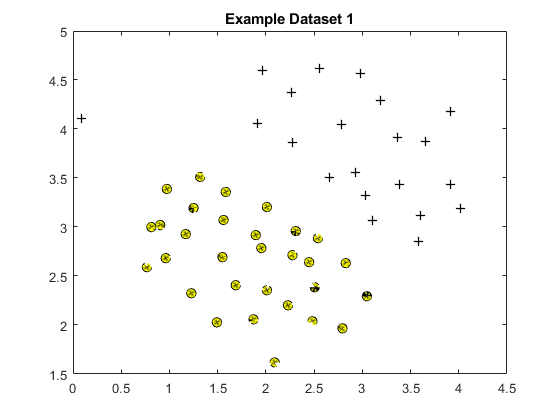


% Load from ex6data1: 
% You will have X, y in your environment
load('data1.mat');

% Plot training data
plotData(X, y);
title('Example Dataset 1');

## Training Linear SVM

We will try using different values of the *C *parameter with SVMs. Informally, the *C *parameter is a positive value that controls the penalty for misclassified training examples. A large *C *parameter tells the SVM to try to classify all the examples correctly. *C *plays a role similar to $\frac{1}{\lambda }$ where $\lambda$ is the regularization parameter.

% Load from ex6data1: 
% You will have X, y in your environment
load('data1.mat');

fprintf('\nTraining Linear SVM for C = 1\n')


Training Linear SVM for C = 1


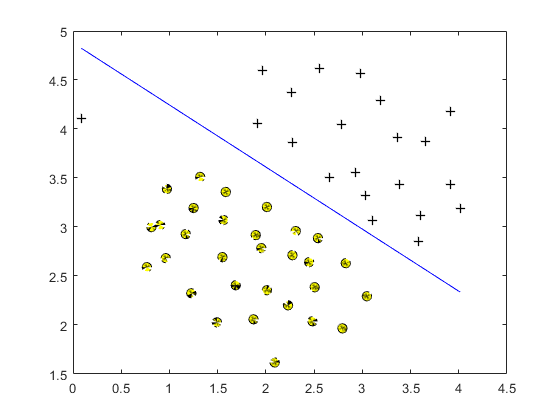

C = 1;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);
visualizeBoundaryLinear(X, y, model);


fprintf('\nTraining Linear SVM for C = 1000\n')


Training Linear SVM for C = 1000


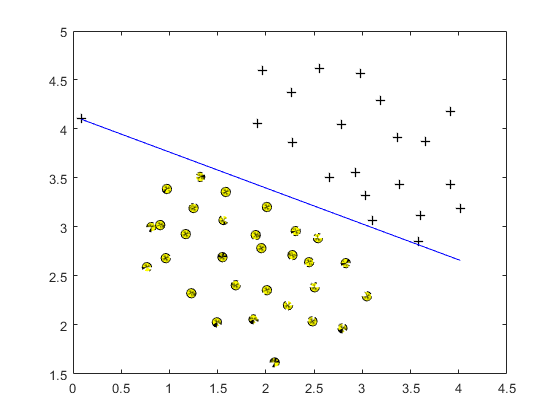

C = 1000;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);
visualizeBoundaryLinear(X, y, model);

## Implementing Gaussian Kernel

**Gaussian Kernel**

To find non-linear decision boundaries with the SVM, we need to first implement a Gaussian kernel. We can think of the Gaussian kernel as a similarity function that measures the “distance” between a pair of examples, $\left(x^{\left(i\right)} ,x^{\left(j\right)} \right)$. The Gaussian kernel is also parameterized by a bandwidth parameter, $\sigma$, which determines how fast the similarity metric decreases (to 0) as the examples are further apart.

The Gaussian kernel function is defined as:


$$K_{\mathrm{gaussian}} \left(x^{\left(i\right)} ,x^{\left(j\right)} \right)=\mathrm{exp}\left(-\frac{||x^{\left(i\right)} -x^{\left(j\right)} ||^2 }{2\sigma^2 }\right)=\mathrm{exp}\left(-\frac{\sum_{k=1}^n {\left({x^{\left(i\right)} }_k -{x^{\left(j\right)} }_k \right)}^2 }{2\sigma^2 }\right)$$


fprintf('\nEvaluating the Gaussian Kernel ...\n')


Evaluating the Gaussian Kernel ...



x1 = [1 2 1]; x2 = [0 4 -1]; sigma = 2;
sim = gaussianKernel(x1, x2, sigma);

fprintf(['Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = %f :' ...
         '\n\t%f\n'], sigma, sim);

Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = 2.000000 :
	0.324652


##  Visualizing non linear dataset

fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


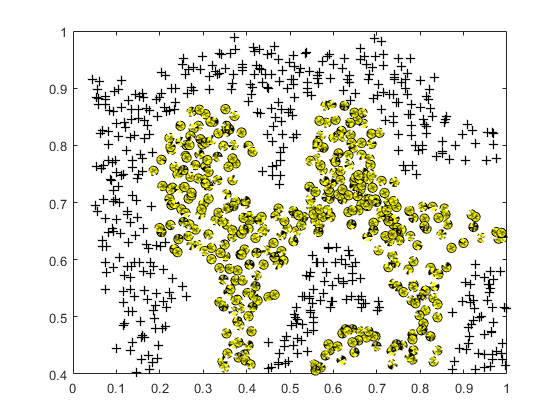


% Load from ex6data2: 
% You will have X, y in your environment
load('data2.mat');

% Plot training data
plotData(X, y);

From the figure, we can obserse that there is no linear decision boundary that separates the positive and negative examples for this dataset. However, by using the Gaussian kernel with the SVM, we will be able to learn a non-linear decision boundary that can perform reasonably well for the dataset.  

## Training SVM with RBF Kernel

fprintf('\nTraining SVM with RBF Kernel (this may take 1 to 2 minutes) ...\n');


Training SVM with RBF Kernel (this may take 1 to 2 minutes) ...


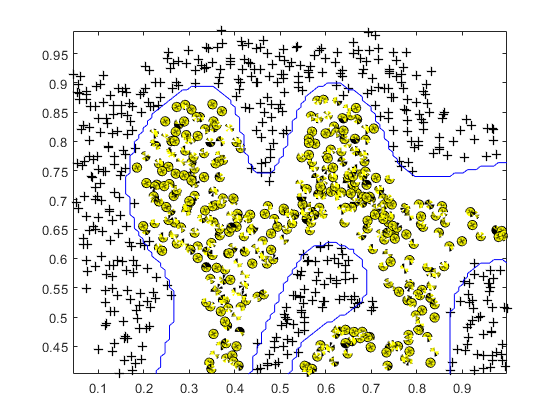


% Load from ex6data2: 
% You will have X, y in your environment
load('data2.mat');

% SVM Parameters
C = 1; sigma = 0.1;

% We set the tolerance and max_passes lower here so that the code will run
% faster. However, in practice, you will want to run the training to
% convergence.
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 
visualizeBoundary(X, y, model);

The decision boundary is able to separate most of the positive and negative examples correctly and follows the contours of the dataset well  

## Another non linear Dataset 

Let's try SVM on another non linear dataset with different parameter for better understanding

fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


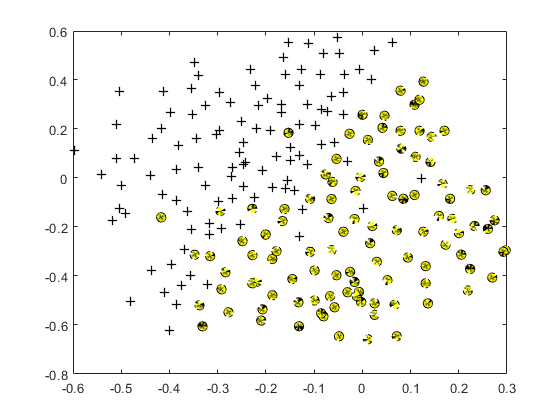


% Load from ex6data3: 
% You will have X, y in your environment
load('data3.mat');

% Plot training data
plotData(X, y);

%  This is a different dataset that you can use to experiment with. Try
%  different values of C and sigma here.
% 

% Try different SVM Parameters here
[C, sigma] = dataset3Params(X, y, Xval, yval)

C = 0.3000

sigma = 0.1000

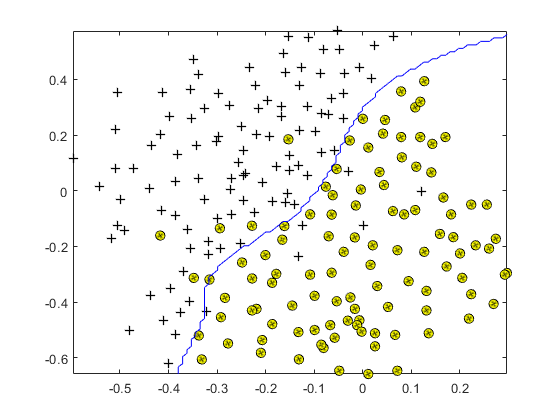

%[C, sigma] = dataset3Params(X, y, Xval, yval);

% Train the SVM
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma));
visualizeBoundary(X, y, model);

## **Spam Classification**

Many email services today provide spam filters that are able to classify emails into spam and non-spam email with high accuracy. We will use SVMs to build your own spam filter.

We will be training a classifier to classify whether a given email, *x*, is spam (*y *= 1) or non-spam (*y *= 0). In particular, you need to convert each email into a feature vector $x\in R^n$

## **Preprocessing Emails**

***> Anyone knows how much it costs to host a web portal ?***

***>Well, it depends on how many visitors youre expecting. This can be anywhere from less than 10 bucks a month to a couple of $100. You should checkout http://www.rackspace.com/ or perhaps Amazon EC2 if youre running something big..***

***To unsubscribe yourself from this mailing list, send an email to:***

***groupname-unsubscribe@egroups.com***

*Sample email*

Before starting on a machine learning task, it is usually insightful to take a look at examples from the dataset. Above sample email contains a URL, an email address (at the end), numbers, and dollar amounts. While many emails would contain similar types of entities (e.g., numbers, other URLs, or other email addresses), the specific entities (e.g., the specific URL or specific dollar amount) will be different in almost every email. Therefore, one method often employed in processing emails is to “normalize” these values, so that all URLs are treated the same, all numbers are treated the same, etc. For example, we could replace each URL in the email with the unique string “httpaddr” to indicate that a URL was present.

This has the effect of letting the spam classifier make a classification decision based on whether *any *URL was present, rather than whether a specific URL was present. This typically improves the performance of a spam classifier, since spammers often randomize the URLs, and thus the odds of seeing any particular URL again in a new piece of spam is very small.

We have implemented the following email preprocessing and normalization steps:  

• **Lower-casing: **The entire email is converted into lower case, so that captialization is ignored (e.g., IndIcaTE is treated the same as Indicate).

• **Stripping HTML: **All HTML tags are removed from the emails. Many emails often come with HTML formatting; we remove all the HTML tags, so that only the content remains.

• **Normalizing URLs: **All URLs are replaced with the text “httpaddr”.

• **Normalizing Email Addresses: **All email addresses are replaced with the text “emailaddr”.

• **Normalizing Numbers: **All numbers are replaced with the text “number”.

• **Normalizing Dollars: **All dollar signs ($) are replaced with the text “dollar”.

• **Word Stemming: **Words are reduced to their stemmed form. For example, “discount”, “discounts”, “discounted” and “discounting” are all replaced with “discount”. Sometimes, the Stemmer actually strips off additional characters from the end, so “include”, “includes”, “included”, and “including” are all replaced with “includ”.

• **Removal of non-words: **Non-words and punctuation have been removed. All white spaces (tabs, newlines, spaces) have all been trimmed to a single space character.

  While preprocessing has left word fragments and non-words, this form turns out to be much easier to work with for performing feature extraction.  

fprintf('\nPreprocessing sample email (emailSample1.txt)\n');


Preprocessing sample email (emailSample1.txt)



% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);


==== Processed Email ====




% Print Stats
fprintf('Word Indices: \n');

Word Indices: 


fprintf(' %d', word_indices);

fprintf('\n\n');

## **Vocabulary List**

After preprocessing the emails, we have a list of words for each email. The next step is to choose which words we would like to use in our classifier and which we would want to leave out.

We have chosen only the most frequently occuring words as our set of words considered (the vocabulary list). Since words that occur rarely in the training set are only in a few emails, they might cause the model to overfit our training set. The complete vocabulary list is in the filevocab.txt. Our vocabulary list was selected by choosing all words which occur at least a 100 times in the spam corpus, resulting in a list of 1899 words. In practice, a vocabulary list with about 10,000 to 50,000 words is often used.

Given the vocabulary list, we can now map each word in the preprocessed emails into a list of word indices that contains the index of the word in the vocabulary list. The mapping for the sample email. Specifically, in the sample email, the word “anyone” was first normalized to “anyon” and then mapped onto the index 86 in the vocabulary list.  

## **Extracting Features from Emails**

We will now implement the feature extraction that converts each email into a vector in $R^n$. For this exercise, we will be using $n=\not=$words in vocabulary list. Specifically, the feature $x_i \in \left\lbrace 0,1\right\rbrace$for an email corresponds to whether

the *i*-th word in the dictionary occurs in the email. That is, $x_i =1$ if the *i*-th word is in the email and $x_i =0$ if the *i*-th word is not present in the email.

Thus, for a typical email, this feature would look like:


$$x=\left\lbrack \begin{array}{c}
0\\
\ldotp \ldotp \ldotp \\
1\\
0\\
\ldotp \ldotp \ldotp \\
1\\
0\\
\ldotp \ldotp \ldotp \\
0
\end{array}\right\rbrack \in R^n$$


fprintf('\nExtracting features from sample email (emailSample1.txt)\n');


Extracting features from sample email (emailSample1.txt)



% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);


==== Processed Email ====



features      = emailFeatures(word_indices);

% Print Stats
fprintf('Length of feature vector: %d\n', length(features));

Length of feature vector: 1899


fprintf('Number of non-zero entries: %d\n', sum(features > 0));

Number of non-zero entries: 0


**Training SVM for Spam Classification**

spamTrain.mat contains 4000 training examples of spam and non-spam email, while spamTest.mat contains 1000 test examples. Each original email was processed using the processEmail and emailFeatures functions and converted into a vector $x^{\left(i\right)} \in R^{1899}$

After loading the dataset  will proceed to train a SVM to classify between spam (*y *= 1) and non-spam (*y *= 0) emails.

load('spamTrain.mat');

fprintf('\nTraining Linear SVM (Spam Classification)\n')


Training Linear SVM (Spam Classification)


fprintf('(this may take 1 to 2 minutes) ...\n')

(this may take 1 to 2 minutes) ...



C = 0.1;
model = svmTrain(X, y, C, @linearKernel);

p = svmPredict(model, X);

fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

Training Accuracy: 99.825000


**Test Spam Classification**

After training the classifier, we can evaluate it on a test set. We have included a test set in spamTest.mat

load('spamTest.mat');

fprintf('\nEvaluating the trained Linear SVM on a test set ...\n')


Evaluating the trained Linear SVM on a test set ...



p = svmPredict(model, Xtest);

fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

Test Accuracy: 98.900000


## Implementation of functions

Implementation of plotData

function plotData(X, y)
%PLOTDATA Plots the data points X and y into a new figure 
%   PLOTDATA(x,y) plots the data points with + for the positive examples
%   and o for the negative examples. X is assumed to be a Mx2 matrix.
%
% Note: This was slightly modified such that it expects y = 1 or y = 0

% Find Indices of Positive and Negative Examples
pos = find(y == 1); neg = find(y == 0);

% Plot Examples
plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 1, 'MarkerSize', 7)
hold on;
plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7)
hold off;

end

Implementation of visualizeBoundary

function visualizeBoundary(X, y, model, varargin)
%VISUALIZEBOUNDARY plots a non-linear decision boundary learned by the SVM
%   VISUALIZEBOUNDARYLINEAR(X, y, model) plots a non-linear decision 
%   boundary learned by the SVM and overlays the data on it

% Plot the training data on top of the boundary
plotData(X, y)

% Make classification predictions over a grid of values
x1plot = linspace(min(X(:,1)), max(X(:,1)), 100)';
x2plot = linspace(min(X(:,2)), max(X(:,2)), 100)';
[X1, X2] = meshgrid(x1plot, x2plot);
vals = zeros(size(X1));
for i = 1:size(X1, 2)
   this_X = [X1(:, i), X2(:, i)];
   vals(:, i) = svmPredict(model, this_X);
end

% Plot the SVM boundary
hold on
contour(X1, X2, vals, [1 1], 'b');
hold off;

end

Implementation of visualizeBoundaryLinear

function visualizeBoundaryLinear(X, y, model)
%VISUALIZEBOUNDARYLINEAR plots a linear decision boundary learned by the
%SVM
%   VISUALIZEBOUNDARYLINEAR(X, y, model) plots a linear decision boundary 
%   learned by the SVM and overlays the data on it

w = model.w;
b = model.b;
xp = linspace(min(X(:,1)), max(X(:,1)), 100);
yp = - (w(1)*xp + b)/w(2);
plotData(X, y);
hold on;
plot(xp, yp, '-b'); 
hold off

end

Implementation of svmTrain

function [model] = svmTrain(X, Y, C, kernelFunction, ...
                            tol, max_passes)
%SVMTRAIN Trains an SVM classifier using a simplified version of the SMO 
%algorithm. 
%   [model] = SVMTRAIN(X, Y, C, kernelFunction, tol, max_passes) trains an
%   SVM classifier and returns trained model. X is the matrix of training 
%   examples.  Each row is a training example, and the jth column holds the 
%   jth feature.  Y is a column matrix containing 1 for positive examples 
%   and 0 for negative examples.  C is the standard SVM regularization 
%   parameter.  tol is a tolerance value used for determining equality of 
%   floating point numbers. max_passes controls the number of iterations
%   over the dataset (without changes to alpha) before the algorithm quits.
%
% Note: This is a simplified version of the SMO algorithm for training
%       SVMs. In practice, if you want to train an SVM classifier, we
%       recommend using an optimized package such as:  
%
%           LIBSVM   (http://www.csie.ntu.edu.tw/~cjlin/libsvm/)
%           SVMLight (http://svmlight.joachims.org/)
%
%

if ~exist('tol', 'var') || isempty(tol)
    tol = 1e-3;
end

if ~exist('max_passes', 'var') || isempty(max_passes)
    max_passes = 5;
end

% Data parameters
m = size(X, 1);
n = size(X, 2);

% Map 0 to -1
Y(Y==0) = -1;

% Variables
alphas = zeros(m, 1);
b = 0;
E = zeros(m, 1);
passes = 0;
eta = 0;
L = 0;
H = 0;

% Pre-compute the Kernel Matrix since our dataset is small
% (in practice, optimized SVM packages that handle large datasets
%  gracefully will _not_ do this)
% 
% We have implemented optimized vectorized version of the Kernels here so
% that the svm training will run faster.
if strcmp(func2str(kernelFunction), 'linearKernel')
    % Vectorized computation for the Linear Kernel
    % This is equivalent to computing the kernel on every pair of examples
    K = X*X';
elseif strfind(func2str(kernelFunction), 'gaussianKernel')
    % Vectorized RBF Kernel
    % This is equivalent to computing the kernel on every pair of examples
    X2 = sum(X.^2, 2);
    K = bsxfun(@plus, X2, bsxfun(@plus, X2', - 2 * (X * X')));
    K = kernelFunction(1, 0) .^ K;
else
    % Pre-compute the Kernel Matrix
    % The following can be slow due to the lack of vectorization
    K = zeros(m);
    for i = 1:m
        for j = i:m
             K(i,j) = kernelFunction(X(i,:)', X(j,:)');
             K(j,i) = K(i,j); %the matrix is symmetric
        end
    end
end

% Train
%fprintf('\nTraining ...');
dots = 12;
while passes < max_passes
            
    num_changed_alphas = 0;
    for i = 1:m
        
        % Calculate Ei = f(x(i)) - y(i) using (2). 
        % E(i) = b + sum (X(i, :) * (repmat(alphas.*Y,1,n).*X)') - Y(i);
        E(i) = b + sum (alphas.*Y.*K(:,i)) - Y(i);
        
        if ((Y(i)*E(i) < -tol && alphas(i) < C) || (Y(i)*E(i) > tol && alphas(i) > 0))
            
            % In practice, there are many heuristics one can use to select
            % the i and j. In this simplified code, we select them randomly.
            j = ceil(m * rand());
            while j == i  % Make sure i \neq j
                j = ceil(m * rand());
            end

            % Calculate Ej = f(x(j)) - y(j) using (2).
            E(j) = b + sum (alphas.*Y.*K(:,j)) - Y(j);

            % Save old alphas
            alpha_i_old = alphas(i);
            alpha_j_old = alphas(j);
            
            % Compute L and H by (10) or (11). 
            if (Y(i) == Y(j))
                L = max(0, alphas(j) + alphas(i) - C);
                H = min(C, alphas(j) + alphas(i));
            else
                L = max(0, alphas(j) - alphas(i));
                H = min(C, C + alphas(j) - alphas(i));
            end
           
            if (L == H)
                % continue to next i. 
                continue;
            end

            % Compute eta by (14).
            eta = 2 * K(i,j) - K(i,i) - K(j,j);
            if (eta >= 0)
                % continue to next i. 
                continue;
            end
            
            % Compute and clip new value for alpha j using (12) and (15).
            alphas(j) = alphas(j) - (Y(j) * (E(i) - E(j))) / eta;
            
            % Clip
            alphas(j) = min (H, alphas(j));
            alphas(j) = max (L, alphas(j));
            
            % Check if change in alpha is significant
            if (abs(alphas(j) - alpha_j_old) < tol)
                % continue to next i. 
                % replace anyway
                alphas(j) = alpha_j_old;
                continue;
            end
            
            % Determine value for alpha i using (16). 
            alphas(i) = alphas(i) + Y(i)*Y(j)*(alpha_j_old - alphas(j));
            
            % Compute b1 and b2 using (17) and (18) respectively. 
            b1 = b - E(i) ...
                 - Y(i) * (alphas(i) - alpha_i_old) *  K(i,j)' ...
                 - Y(j) * (alphas(j) - alpha_j_old) *  K(i,j)';
            b2 = b - E(j) ...
                 - Y(i) * (alphas(i) - alpha_i_old) *  K(i,j)' ...
                 - Y(j) * (alphas(j) - alpha_j_old) *  K(j,j)';

            % Compute b by (19). 
            if (0 < alphas(i) && alphas(i) < C)
                b = b1;
            elseif (0 < alphas(j) && alphas(j) < C)
                b = b2;
            else
                b = (b1+b2)/2;
            end

            num_changed_alphas = num_changed_alphas + 1;

        end
        
    end
    
    if (num_changed_alphas == 0)
        passes = passes + 1;
    else
        passes = 0;
    end

    %fprintf('.');
    dots = dots + 1;
    if dots > 78
        dots = 0;
        %fprintf('\n');
    end
    if exist('OCTAVE_VERSION')
        fflush(stdout);
    end
end
%fprintf(' Done! \n\n');

% Save the model
idx = alphas > 0;
model.X= X(idx,:);
model.y= Y(idx);
model.kernelFunction = kernelFunction;
model.b= b;
model.alphas= alphas(idx);
model.w = ((alphas.*Y)'*X)';

end

Implementation of gaussianKernel

function sim = gaussianKernel(x1, x2, sigma)
%RBFKERNEL returns a radial basis function kernel between x1 and x2
%   sim = gaussianKernel(x1, x2) returns a gaussian kernel between x1 and x2
%   and returns the value in sim

% Ensure that x1 and x2 are column vectors
x1 = x1(:); x2 = x2(:);

% You need to return the following variables correctly.
sim = 0;

diff = (x1 - x2);

diff_sqr = diff.^2;

total = sum(diff_sqr);

sim = exp(-total / (2 * (sigma^2)));

% =============================================================
end

Implementation of dataset3Params

function [C, sigma] = dataset3Params(X, y, Xval, yval)
%DATASET3PARAMS returns your choice of C and sigma for Part 3 of the exercise
%where you select the optimal (C, sigma) learning parameters to use for SVM
%with RBF kernel
%   [C, sigma] = DATASET3PARAMS(X, y, Xval, yval) returns your choice of C and 
%   sigma. We should complete this function to return the optimal C and 
%   sigma based on a cross-validation set.
%

% You need to return the following variables correctly.
arr = [0.01; 0.03; 0.1; 0.3; 1; 3; 10; 30];
min_err_rate = 1;

for i = 1:size(arr,1)
   for j = 1:size(arr,1)
       model= svmTrain(X, y, arr(i), @(x1, x2) gaussianKernel(x1, x2, arr(j))); 
       predictions = svmPredict(model, Xval);
       err_rate = mean(double(predictions ~= yval));
       if min_err_rate > err_rate
           min_err_rate = err_rate; 
           C = arr(i);
           sigma = arr(j);
       end
   end 
    
end

end

Implementation of processEmail

function word_indices = processEmail(email_contents)
%PROCESSEMAIL preprocesses a the body of an email and
%returns a list of word_indices 
%   word_indices = PROCESSEMAIL(email_contents) preprocesses 
%   the body of an email and returns a list of indices of the 
%   words contained in the email. 
%

% Load Vocabulary
vocabList = getVocabList();

% Init return value
word_indices = [];

% ========================== Preprocess Email ===========================

% Find the Headers ( \n\n and remove )
% Uncomment the following lines if you are working with raw emails with the
% full headers

% hdrstart = strfind(email_contents, ([char(10) char(10)]));
% email_contents = email_contents(hdrstart(1):end);

% Lower case
email_contents = lower(email_contents);

% Strip all HTML
% Looks for any expression that starts with < and ends with > and replace
% and does not have any < or > in the tag it with a space
email_contents = regexprep(email_contents, '<[^<>]+>', ' ');

% Handle Numbers
% Look for one or more characters between 0-9
email_contents = regexprep(email_contents, '[0-9]+', 'number');

% Handle URLS
% Look for strings starting with http:// or https://
email_contents = regexprep(email_contents, ...
                           '(http|https)://[^\s]*', 'httpaddr');

% Handle Email Addresses
% Look for strings with @ in the middle
email_contents = regexprep(email_contents, '[^\s]+@[^\s]+', 'emailaddr');

% Handle $ sign
email_contents = regexprep(email_contents, '[$]+', 'dollar');


% ========================== Tokenize Email ===========================

% Output the email to screen as well
fprintf('\n==== Processed Email ====\n\n');

% Process file
l = 0;

while ~isempty(email_contents)

    % Tokenize and also get rid of any punctuation
    [str, email_contents] = ...
       strtok(email_contents, ...
              [' @$/#.-:&*+=[]?!(){},''">_<;%' newline char(13)]);
   
    % Remove any non alphanumeric characters
    str = regexprep(str, '[^a-zA-Z0-9]', '');

    % Stem the word 
    % (the porterStemmer sometimes has issues, so we use a try catch block)
    try str = porterStemmer(strtrim(str)); 
    catch str = ''; continue;
    end

    % Skip the word if it is too short
    if length(str) < 1
       continue;
    end
    for i = 1:size(vocabList,1)
        word = vocabList{i};
        if  strcmp(word,str)==1
            word_indices = [word_indices; i];
            break;
        end
    end
    % Look up the word in the dictionary and add to word_indices if
    % found

    % Print to screen, ensuring that the output lines are not too long
    if (l + length(str) + 1) > 78
        %fprintf('\n');
        l = 0;
    end
    %fprintf('%s ', str);
    l = l + length(str) + 1;

end

% Print footer
fprintf('\n\n=========================\n');

end

Implementation of readFile

function file_contents = readFile(filename)
%READFILE reads a file and returns its entire contents 
%   file_contents = READFILE(filename) reads a file and returns its entire
%   contents in file_contents
%

% Load File
fid = fopen(filename);
if fid
    file_contents = fscanf(fid, '%c', inf);
    fclose(fid);
else
    file_contents = '';
    fprintf('Unable to open %s\n', filename);
end

end

Implementation of emailFeatures

function x = emailFeatures(word_indices)
%EMAILFEATURES takes in a word_indices vector and produces a feature vector
%from the word indices
%   x = EMAILFEATURES(word_indices) takes in a word_indices vector and 
%   produces a feature vector from the word indices. 

% Total number of words in the dictionary
n = 1899;

% You need to return the following variables correctly.
x = zeros(n, 1);

vocabList = getVocabList();
for i = 1:size(word_indices,1)
    indx = word_indices(i);
    x(indx) = 1;
end
end

Implementation of svmPredict

function pred = svmPredict(model, X)
%SVMPREDICT returns a vector of predictions using a trained SVM model
%(svmTrain). 
%   pred = SVMPREDICT(model, X) returns a vector of predictions using a 
%   trained SVM model (svmTrain). X is a mxn matrix where there each 
%   example is a row. model is a svm model returned from svmTrain.
%   predictions pred is a m x 1 column of predictions of {0, 1} values.
%

% Check if we are getting a column vector, if so, then assume that we only
% need to do prediction for a single example
if (size(X, 2) == 1)
    % Examples should be in rows
    X = X';
end

% Dataset 
m = size(X, 1);
p = zeros(m, 1);
pred = zeros(m, 1);

if strcmp(func2str(model.kernelFunction), 'linearKernel')
    % We can use the weights and bias directly if working with the 
    % linear kernel
    p = X * model.w + model.b;
elseif strfind(func2str(model.kernelFunction), 'gaussianKernel')
    % Vectorized RBF Kernel
    % This is equivalent to computing the kernel on every pair of examples
    X1 = sum(X.^2, 2);
    X2 = sum(model.X.^2, 2)';
    K = bsxfun(@plus, X1, bsxfun(@plus, X2, - 2 * X * model.X'));
    K = model.kernelFunction(1, 0) .^ K;
    K = bsxfun(@times, model.y', K);
    K = bsxfun(@times, model.alphas', K);
    p = sum(K, 2);
else
    % Other Non-linear kernel
    for i = 1:m
        prediction = 0;
        for j = 1:size(model.X, 1)
            prediction = prediction + ...
                model.alphas(j) * model.y(j) * ...
                model.kernelFunction(X(i,:)', model.X(j,:)');
        end
        p(i) = prediction + model.b;
    end
end

% Convert predictions into 0 / 1
pred(p >= 0) =  1;
pred(p <  0) =  0;

end

Implementation of getVocabList

function vocabList = getVocabList()
%GETVOCABLIST reads the fixed vocabulary list in vocab.txt and returns a
%cell array of the words
%   vocabList = GETVOCABLIST() reads the fixed vocabulary list in vocab.txt 
%   and returns a cell array of the words in vocabList.


%% Read the fixed vocabulary list
fid = fopen('vocab.txt');

% Store all dictionary words in cell array vocab{}
n = 1899;  % Total number of words in the dictionary

% For ease of implementation, we use a struct to map the strings => integers
% In practice, you'll want to use some form of hashmap
vocabList = cell(n, 1);
for i = 1:n
    % Word Index (can ignore since it will be = i)
    fscanf(fid, '%d', 1);
    % Actual Word
    vocabList{i} = fscanf(fid, '%s', 1);
end
fclose(fid);

end